# SVM HOG

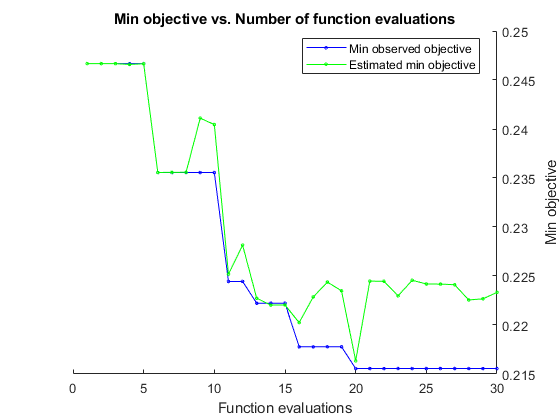

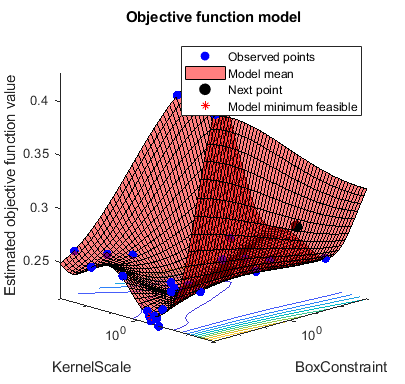

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstrain-|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    | t            |              |
|=====================================================================================================|
|    1 | Best   |     0.24667 |      7.9965 |     0.24667 |     0.24667 |        4.087 |       1.8189 |
|    2 | Accept |     0.24667 |      61.446 |     0.24667 |     0.24667 |       500.79 |     0.021002 |
|    3 | Accept |     0.24667 |      23.438 |     0.24667 |     0.24667 |    0.0086044 |     0.028051 |
|    4 | Accept |     0.37556 |      84.101 |     0.24667 |     0.24659 |       37.253 |       970.27 |
|    5 | Accept |     0.42778 |      73.542 |     0.24667 |     0.24665 |    0.0011905 |    0.0010011 |
|    6 | Best   |     0.23556 |      7.8519 |     0.23556 |     

classifier =   ClassificationSVM
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [F    M]
                       ScoreTransform: 'none'
                      NumObservations: 900
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                                Alpha: [568×1 single]
                                 Bias: 1.0936
                     KernelParameters: [1×1 struct]
                       BoxConstraints: [900×1 double]
                      ConvergenceInfo: [1×1 struct]
                      IsSupportVector: [900×1 logical]
                               Solver: 'SMO'


  Properties, Methods


clc
clear 
close all

i = imageDatastore('New Data\*\*.png','LabelSource','foldernames');

tbl = countEachLabel(i);
minSetCount = min(tbl{:,2});
i = splitEachLabel(i, minSetCount, 'randomize');

i.ReadSize = 1500;
i.ReadFcn = @(loc)imresize(imread(loc),[128 , 128]);


[trainingSet, validationSet] = splitEachLabel(i, 0.6, 'randomize');

img = readimage(trainingSet, 206);
% Extract HOG features and HOG visualization
[hog_8x8, vis8x8] = extractHOGFeatures(img,'CellSize',[8 8]);


cellSize = [8 8];
hogFeatureSize = length(hog_8x8);

numImages = numel(trainingSet.Files);
trainingFeatures = zeros(numImages, hogFeatureSize, 'single');

for i = 1:numImages
    img = readimage(trainingSet,i);
    trainingFeatures(i,:) = extractHOGFeatures(img,'CellSize',cellSize); 
end

% Get labels for each image.
trainingLabels = trainingSet.Labels;

% fitcecoc uses SVM learners and a 'One-vs-One' encoding scheme.
classifier = fitcsvm(trainingFeatures, trainingLabels,'OptimizeHyperparameters','auto')


% Extract HOG features from the test set. The procedure is similar to what
% was shown earlier and is encapsulated as a helper function for brevity.
[testFeatures, testLabels] = helperExtractHOGFeaturesFromImageSet(validationSet,hogFeatureSize,cellSize);

% Make class predictions using the test features.
predictedLabels = predict(classifier, testFeatures);

% Tabulate the results using a confusion matrix.
confMat = confusionmat(testLabels, predictedLabels)

confMat =    234    66
    70   230


confMat = bsxfun(@rdivide,confMat,sum(confMat,2));

mean(diag(confMat))*100

ans = 77.3333

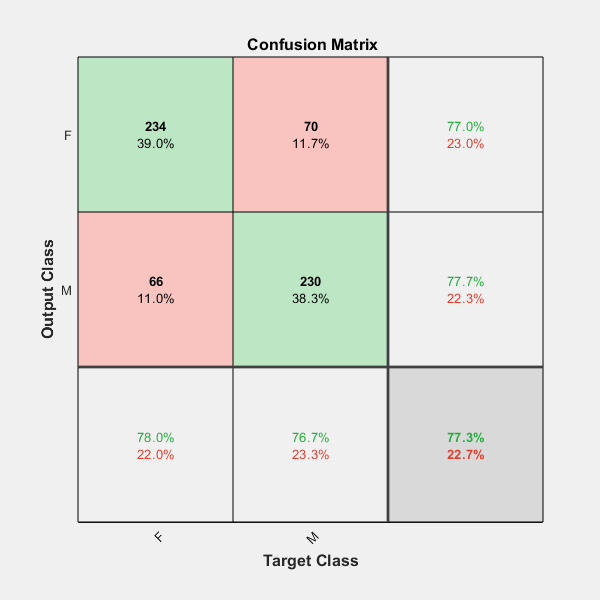

recall = zeros(2,1);
precision = zeros(2,1);
plotconfusion(testLabels, predictedLabels)

for i =1:size(confMat,1)
    recall(i)=confMat(i,i)/sum(confMat(i,:));
end
recall(isnan(recall))=[];
Recall=(sum(recall)/size(confMat,1))*100

Recall = 77.3333

for i =1:size(confMat,1)
    precision(i)=confMat(i,i)/sum(confMat(:,i));
end
Precision=(sum(precision)/size(confMat,1))*100

Precision = 77.3382

%%% F-score
F_score=(2*Recall*Precision/(Precision+Recall))

F_score = 77.3358

function [features, setLabels] = helperExtractHOGFeaturesFromImageSet(imds, hogFeatureSize, cellSize)
% Extract HOG features from an imageDatastore.

setLabels = imds.Labels;
numImages = numel(imds.Files);
features  = zeros(numImages, hogFeatureSize, 'single');

% Process each image and extract features
for j = 1:numImages
    img = readimage(imds, j);
    
    features(j, :) = extractHOGFeatures(img,'CellSize',cellSize);
end
end